## FA3 strain

modelName = 'FA234';
open_system(modelName)
set_param(modelName + "/Manual Switch1",'sw','1')
set_param(modelName + "/Manual Switch2",'sw','1')
set_param(modelName + "/Manual Switch3",'sw','1')
set_param(modelName + "/Model selection (manual)",'Value','2') % FA4 model

p = sdo.getParameterFromModel(modelName,{'IPTG','addTime','arabi'});

% IPTG
p(1).Value = 100;
p(1).Minimum = 0;
p(1).Maximum = 1000;
p(1).Scale = 1000;
p(1).Free = 1;

% Arabinose adding time
p(2).Value = 0;
p(2).Minimum = 0;
p(2).Maximum = 25;
p(2).Scale = 25;
p(2).Free = 1;

% Arabinose concentration
p(3).Value = 0.5;
p(3).Minimum = 0;
p(3).Maximum = 1;
p(3).Scale = 1;
p(3).Free = 1;

options = sdo.OptimizeOptions;
options.Method = 'fmincon';

Exp = sdo.Experiment(modelName);
Exp = setEstimatedValues(Exp,p);

FFASignal = Simulink.SimulationData.Signal;
FFASignal.Name = 'Fatty acid';
FFASignal.BlockPath = modelName + "/GainFA";
FFASignal.PortType = 'outport';
FFASignal.PortIndex = 1;
FFASignal.Values = timeseries((1:25)',(1:25)'); % What does this mean?

Exp.OutputData = FFASignal; % add the signal object to the experiment

Simulator = createSimulator(Exp);
estFcn = @(p) optInputObjective(p,Simulator,Exp);

val = optInputObjective(p,Simulator,Exp);
val.F

ans = -1.2162

tic
[optInput,optInputInfo] = sdo.optimize(estFcn,p,options)


 最適化開始時間 18-Nov-2023 22:04:13

                               max                     First-order 
 Iter F-count        f(x)   constraint    Step-size    optimality
    0      6     -1.21616            0
    1     16     -1.40429            0        0.492         3.12
    2     22     -1.58614            0        0.614         1.78
    3     28     -1.84452            0        0.356         2.76
    4     34     -1.86576            0        0.139         1.75
    5     40     -2.02851            0        0.111         1.26
    6     47     -2.09382            0        0.364         1.92
    7     54     -2.10689            0        0.127         3.55
    8     60     -2.14752            0        0.114         1.57
    9     66     -2.19413            0        0.112         1.12
   10     72     -2.20028            0       0.0352        0.316
   11     77     -2.20028            0     0.000869        0.316
局所的最小値の可能性があります。制約が満たされました。

現在のステップ サイズがステップ サイズの許容誤差値未満で、
制約が制約の許容誤差値の範囲内で満たされ

optInputInfo = フィールドをもつ struct :
               F: -2.2003
       Gradients: [1×1 struct]
        exitflag: 2
      iterations: 11
    SolverOutput: [1×1 struct]
           Stats: [1×1 struct]


toc

経過時間は 57.521660 秒です。


maxFFA_FA4 = -optInputInfo.SolverOutput.fval;

save('optInput_FA4','optInput')
sdo.setValueInModel(modelName,optInput);

## Plot the convex curve

% spv_length = 26;
addTimeOpt = optInput(2).Value;
setPointValuesIPTG = logspace(0,3,100); % 1-1000 uM IPTG
setPointValuesAddTime = [0 5 addTimeOpt 15 20 25]; % 0-25 h arabinose adding time

for i =  1:1:length(setPointValuesAddTime)
    for j = 1:1:length(setPointValuesIPTG)
        in(j) = Simulink.SimulationInput(modelName);
        in(j) = in(j).setBlockParameter(modelName + "/To optimize input",...
        'Value',num2str(setPointValuesIPTG(j)));
        in(j) = in(j).setBlockParameter(modelName + "/Arabinose",...
            'Time',num2str(setPointValuesAddTime(i)));
    end
    out_FA4{i} = sim(in,'ShowSimulationManager','off','ShowProgress','off')
end

out_FA4 = 1×1 の cell 配列
    {1×100 Simulink.SimulationOutput}


out_FA4 = 1×2 の cell 配列
    {1×100 Simulink.SimulationOutput}    {1×100 Simulink.SimulationOutput}


out_FA4 = 1×3 の cell 配列
    {1×100 Simulink.SimulationOutput}    {1×100 Simulink.SimulationOutput}    {1×100 Simulink.SimulationOutput}


out_FA4 = 1×4 の cell 配列
    {1×100 Simulink.SimulationOutput}    {1×100 Simulink.SimulationOutput}    {1×100 Simulink.SimulationOutput}    {1×100 Simulink.SimulationOutput}


out_FA4 = 1×5 の cell 配列
    {1×100 Simulink.SimulationOutput}    {1×100 Simulink.SimulationOutput}    {1×100 Simulink.SimulationOutput}    {1×100 Simulink.SimulationOutput}    {1×100 Simulink.SimulationOutput}


out_FA4 = 1×6 の cell 配列
    {1×100 Simulink.SimulationOutput}    {1×100 Simulink.SimulationOutput}    {1×100 Simulink.SimulationOutput}    {1×100 Simulink.SimulationOutput}    {1×100 Simulink.SimulationOutput}    {1×100 Simulink.SimulationOutput}


FFA_end_FA4 = zeros(length(setPointValuesIPTG),1 + length(setPointValuesAddTime));
FFA_end_FA4(:,1) = setPointValuesIPTG;
for i = 1:1:length(setPointValuesAddTime)
    for j = 1:1:length(setPointValuesIPTG)
        FFA_end_FA4(j,1 + i) = out_FA4{i}(j).logsout{1}.Values.Data(end);
    end
end

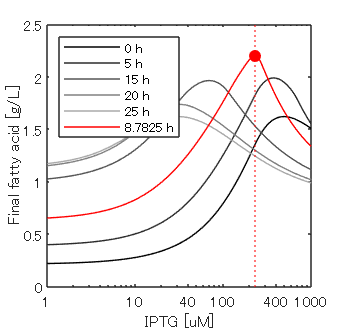

grayscale = gray(7);
grayscale = grayscale(2:end,:);

figure('Position', [120 120 250 240]);
plot(FFA_end_FA4(:,1),FFA_end_FA4(:,[2 3 5 6 7]),'-')
colororder(greyscale)
hold on
plot(FFA_end_FA4(:,1),FFA_end_FA4(:,4),'-r')
xline(optInput(1).Value,'r:')
xlim([1 1000])
ylim([0 2.5])
xlabel('IPTG [uM]')
xticks([1 10 40 100 400 1000])
% yticks([0 20 40 60 80])
ylabel('Final fatty acid [g/L]')
% hold on
plot(optInput(1).Value,maxFFA_FA4,'ro','MarkerFaceColor','r')
hold off
set(gca,'xscale','log')
legend({'0 h' '5 h' '15 h' '20 h' '25 h' append(num2str(addTimeOpt),' h')},'Location','northwest')